### PHYSICS 434 

### LAB 5 Final

**11.10.19**

**Avi Soval **

**Collaborators: Thomas Conaway, Jeff Jiang **

## Optimizing Event Selection for LHC Higgs Detection against Background QCD

**The objective of this lab is to optimize event selection criteria in the LHC data to improve the discovery sensitivity for a potential Higgs particle detection. In this sense, the lab is similar to Lab 3, where we defined a sensitivity threshold that maximized the ratio of accurate omissions to accurate comissions for a given dataset. However, given the significant QCD contamination in the LHC background data, a 5-sigma sensitivity that qualifies as an observation has not yet been established. Thus, our goal is to improve the current discovery sensitivity without negatively impacting the true omission to comission ratio. **

### **Higgs and LHC Backgroud **

**The Large Hadron Collider (LHC) is quite possibly the largest, most powerful, and most complicated machine mankind has ever built. Designed to help physicists peer deeper than ever before into the realm of particle physics, the LHC simulates the highly energetic conditions of the universe in the immediate aftermath of the Big Bang. It does so by accelerating two proton beams in opposite directions to nearly the speed of light; the resulting collisions produce a cascade of subatomic particles and an avalanche of data for the physicists to parse through. These highly energetic, unstable particles rapidly decay into other products, and we can reconstruct the properties of the originally synthesized particle by analyzing the behavior of its jets and decay. **

**Of titanic importance was the discovery of the Higgs Boson by the LHC in 2012 - the particle is a quantized excitation of the Higgs Field. Many fundamental particles, despite being theoretically massless due to their multitude of symmetries, are able to 'generate mass' by interacting with this field. But proving the existence of this Higgs Field proved too elusive for almost four decades, until the breakthrough seven years ago. It is possible to confirm the presence of a field by observing an excitation of it - and a quantized excitation of a field manifests as a particle - the Higgs Boson. **

### **Data Structure **

**As stated earlier, the objective of this lab is to optimize a set of selection criteria for Higgs detections to enhance the discovery sensitivity of our approach. We analyze two training datasets to help determine these optimum selection criteria - the first dataset is confirmed Higgs signal data, while the second set is the vast QCD contamination in the background. For each jet analyzed, data for 14 distinct variables is recorded. The 14 variables are: [pt, eta, phi, mass, ee2, ee3, d2, angularity, t1, t2, t3, t21, t32, ktDeltaR]. The explanations for a few of the more important variables that we will analyze are given below: **

- **'*****pt*****' = Transverse Momentum : The momentum of the jet perpendicular to the beam axis - positive Higgs detections are expected to have high transverse momentums **

- **'eta' = Pseudorapidity : The pseudorapidity describes the angle of the jet relative to the beam axis, i.e the angle in the yz plane relative to the z axis that describes the beam **

- **'phi' = Azimuthal Angle : The angle of the jet in the xy plane - perpendicular to the beam axis. If we assume that each collision is truly random and independent of all others, then we should expect that the azimuthal angles for our datasets should be evenly spread over 360 degrees. **

- **'mass' = Invariant Mass : Invariant mass of the jet in GeV**

- **'t32' = N-Subjettiness : A metric that serves as an effective discriminating agent given a jet invariant mass and the background QCD invariant mass, used to improve the tagging efficiences and discovery potentials for 'boosted' decaying objects as observed in Higgs decay products**

**The datasets examined in this lab are selected to be within a range of 250 - 500 GeV; it is an artifical limit on the structure of the data and not actually indicative of any particular physical phenomena. **

### **Preliminary Data Exploration **

h5disp("higgs_100000_pt_250_500.h5"); 

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp('qcd_100000_pt_250_500.h5'); 

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000



higgs = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500'); 
qcd = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500'); 

higgs = array2table(higgs,'RowNames',{'pt';'eta';'phi';'mass';'ee2';'ee3';'d2';'angularity';'t1';'t2';'t3';'t21';'t32';'KtDeltaR'}); 
qcd = array2table(qcd,'RowNames',{'pt';'eta';'phi';'mass';'ee2';'ee3';'d2';'angularity';'t1';'t2';'t3';'t21';'t32';'KtDeltaR'}); 

VariableNames = ["Transverse Momentum (GeV)";"Pseudorapidity";"Azimuthal Angle (rad)";"Invariant Mass";"2-Point ECF Ratio";"3-Point ECF Ratio";"3 to 2 Point ECF Ratio";"Angularity";"t1";"t2";"t3";"t21";"t32";"KtDeltaR"]; 


jetNumber = cell(1,100000);  

for i = 1:length(jetNumber)
    
    text = "Jet_" + i; 
    text = string(text); 
    text = char(text); 
    jetNumber{i} = text; 
    
end

higgs.Properties.VariableNames = jetNumber; 
qcd.Properties.VariableNames = jetNumber; 

higgs = rows2vars(higgs); %swapping rows and columns of the table, Jet # now runs vertically down 
qcd = rows2vars(qcd); 

**We plot first some basic parameters over the first 1000 jets from both the Higgs Signal and the QCD Contamination datasets. The transverse momentum, pseudorapidity, azimuthal angle, and invariant mass are plotted for each set over this range. **

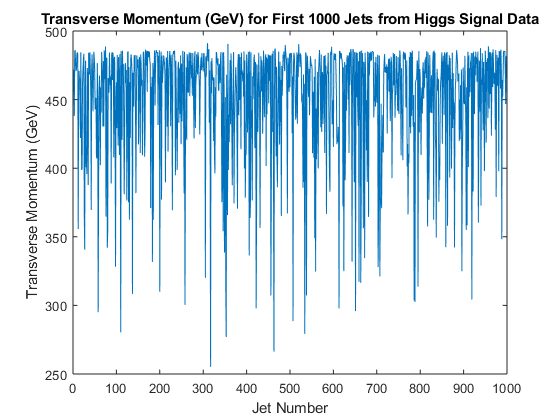

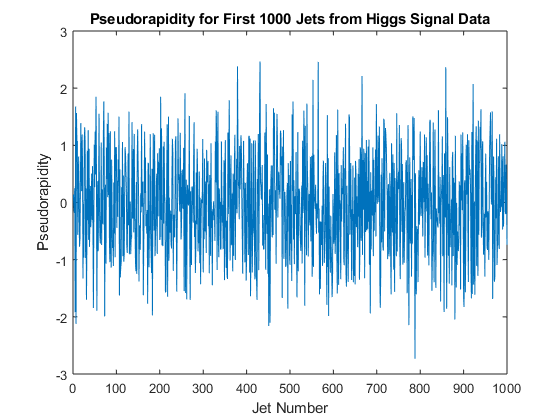

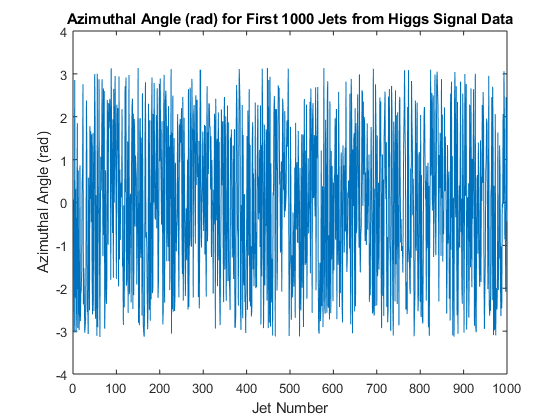

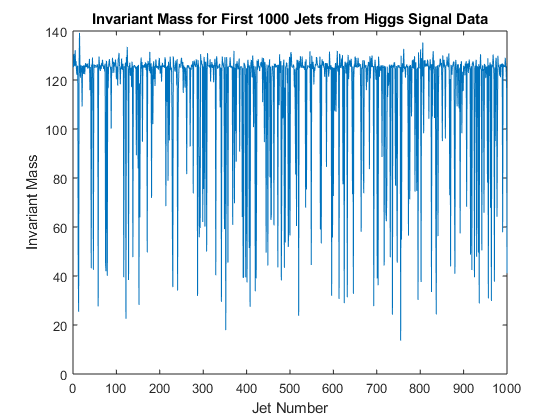

for i = 2:5 
    
    figure(i-1)
    plot(higgs{1:1000,i}); 
    xlabel('Jet Number'); 
    ylabel(VariableNames(i-1)); 
    title(VariableNames(i-1) + " for First 1000 Jets from Higgs Signal Data");    
    
end

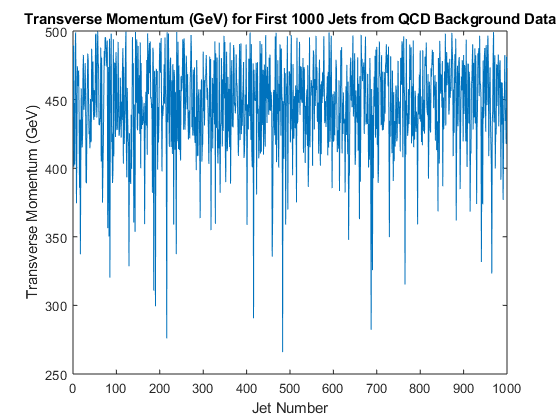

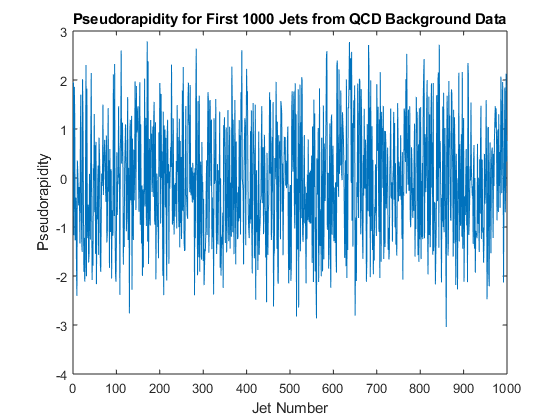

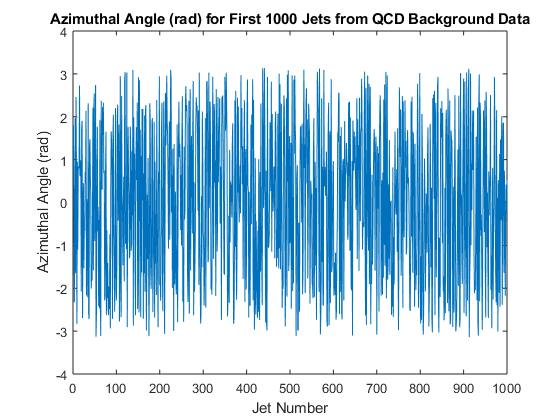

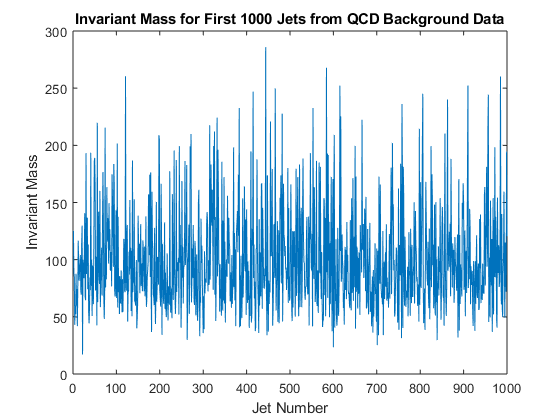

for i = 2:5
    
    figure(i+4)
    plot(qcd{1:1000,i}); 
    xlabel('Jet Number'); 
    ylabel(VariableNames(i-1)); 
    title(VariableNames(i-1) + " for First 1000 Jets from QCD Background Data");    
    
end

**From this preliminary data, we observe a few key things. It seems as if the transverse momentum measured looks like a set of fairly narrow Gaussians, explaining the relatively confined distribution except some sharp outliers. The pseudorapidity for both the Higgs and QCD data seems to be normally distributed around 0, which we would expect if we assumed that each collision was completely random and could produce a jet in any given direction. The same applies to the azimuthal angle measurements for both datasets. However, in the invariant mass datasets, we see significant difference between the Higgs and QCD measurements. For the QCD the invariant mass averages around 50-100 but experiences several sharp peaks to much higher values; the opposite shape takes place for the Higgs data, with a baseline at approximately 130 but with several deep plunges to as low as 20. However, we cannot claim any conclusions from this sample of 1000 out of 100000 jets to be indicative of the data trends for the entire dataset.**

**The goal of this lab is to identify the optimum combinations of variables analyzed that will maximize the probability of correctly detecting a Higgs event from the next lab's pseudo-experiment data. Therefore, we need to discern the discrimination power of each of these variables - or their ability to diffrentiate the signal from the background data. Thus, we must compare the statistical distributions for each variable between the signal and background data. In the following section, we do this by plotting histograms of all 14 variables for both the Higgs and QCD data, and try and fit distributions to the more relevant sets. We then compare the distributions between the signal and background data, and attempt to reconcile them with physical explanations for what is actually happening inside the detector.**

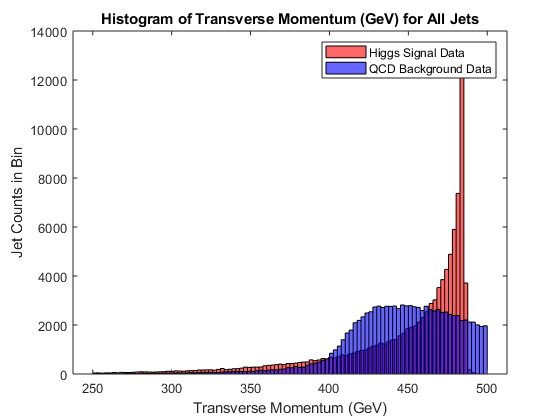

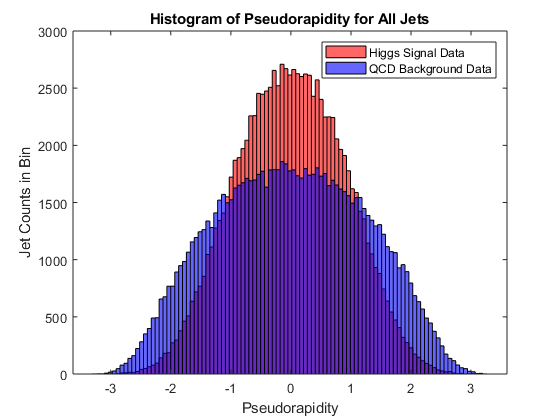

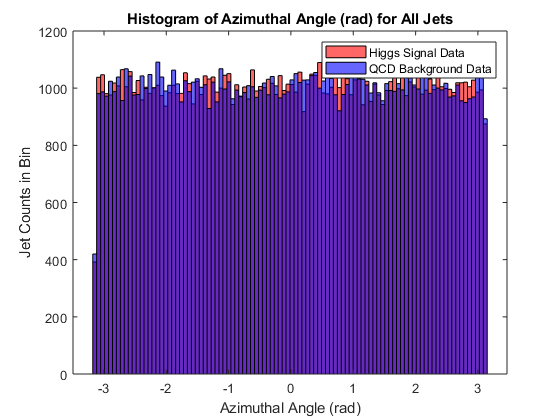

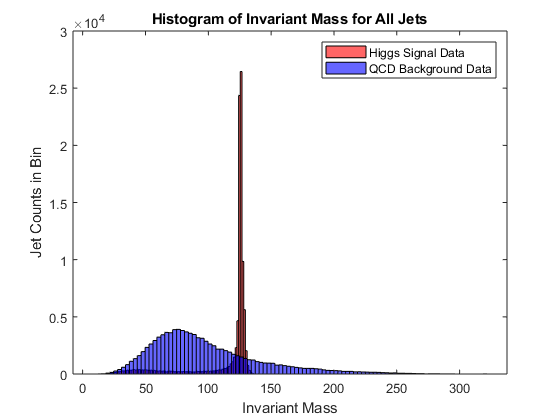

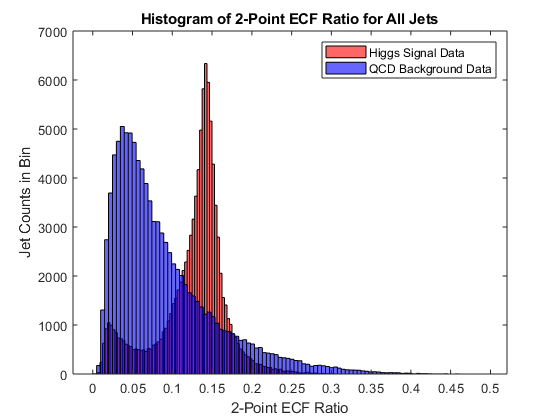

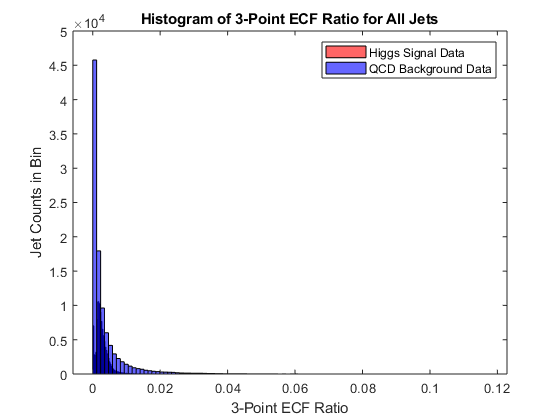

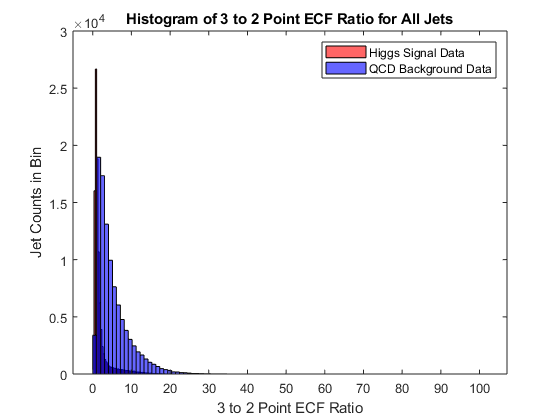

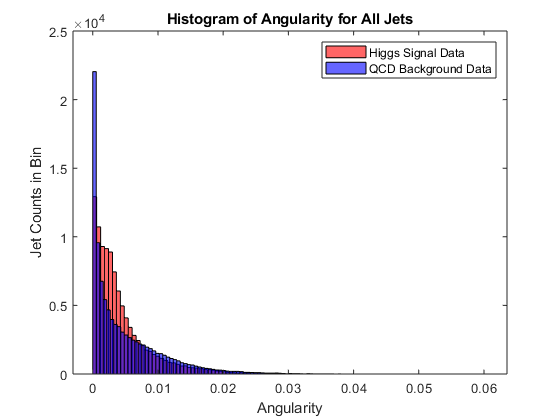

for i = 2:15 
    
    figure(i+9)
    arr(:,i-1,1) = higgs{:,i}; 
    arr(:,i-1,2) = qcd{:,i}; 
    
    histogram(higgs{:,i},'FaceColor','Red',"NumBins",100); 
    hold on 
    histogram(qcd{:,i},'FaceColor','Blue',"NumBins",100);  
    xlabel(VariableNames(i-1)); 
    ylabel("Jet Counts in Bin"); 
    title("Histogram of " + VariableNames(i-1) + " for All Jets"); 
    legend("Higgs Signal Data","QCD Background Data");  
   
end

**We analyze the previous four variables - transverse momentum, pseudorapidity, azimuthal angle, and invariant mass first. Immediately, different trends show up when looking at all the data. Using the Matlab Distribution Filter application, the Higgs data for the Transverse Momentum measurements is most likely an Extreme Value distribution, but the QCD data yields no strong fits. The psuedorapidity for both jets follows a clearly Normal distribution, echoing our finds from the previous section as well. However, the histogram for the Azimuthal angle measurements shows an almost completely even spread of angles for the entire experiment. This is consistent with the jet taking truly random directions after the collision. For the psuedorapidity, we would *****not *****expect the same. Since the psuedorapidity describes the angle of the jet relative to the acual proton beam axis, and since the protons have almost all their momentum along this axis, we would expect the jets to only veer off in a direction close to this axis, since the momentum of each proton is almost exactly the same. This then explains the Normal distribution for the pseudorapidity, in contrast to the truly random distribution for the azimuthal angle. The histogram for the invariant mass is most interesting. The QCD background data looks like a slightly skewed Normal or potentially a Rayleigh distribution, while the Higgs data looks like an extremely concentrated Gaussian or Normal function. However, this is not indicative of some peculiar physical phenomena - since we have artificially selected our Higgs signal, we expect all these candidate jets to fall within the small, very precise range. **

**As discussed earlier, the discrimination power of any of these variables is linked to the difference between the histograms for its Higgs and QCD data. By this metric, the pseudorapidity and azimuthal angle are poor discriminators since all the signal features fall well within or are entirely eclipsed by the background distribution. This means that any measurement of these variables in the signal would be almost impossible to disintguish from he background. Similarly, the 3-Point ECF ratio, 3-2 point ECF, angularity, and t1 variables also have subpar discrminating power. Conversely, the transverse momentum, invariant mass, 2-point ECF, t2, t3, t21, t32, and KtDeltaR are much stronger discriminators, given the much smaller overlap between the signal and background distributions. **

**In the next lab, we will begin considering criteria for the optimum selection of variables to analyze, with the goal of identifying combinations of a few that will yield the largest difference between the signal and background. **